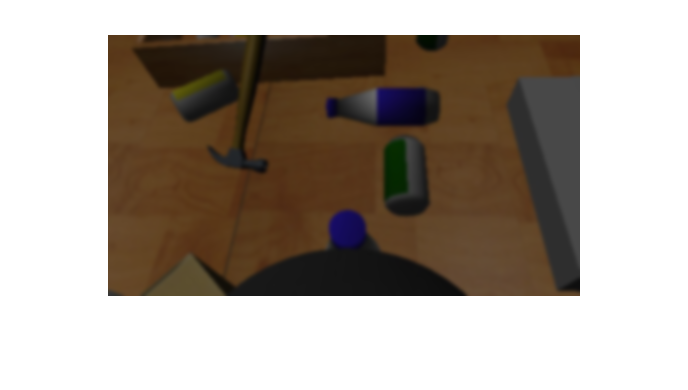

% ------------- VISION MOD --------------------
DIR = 'data/'; img_id = 1; 
path = join([DIR, img_id, ".jpeg"], ""); 

source_img = imread(path); % Get the main image
source_img = imgaussfilt(source_img,2);
imshow(source_img);

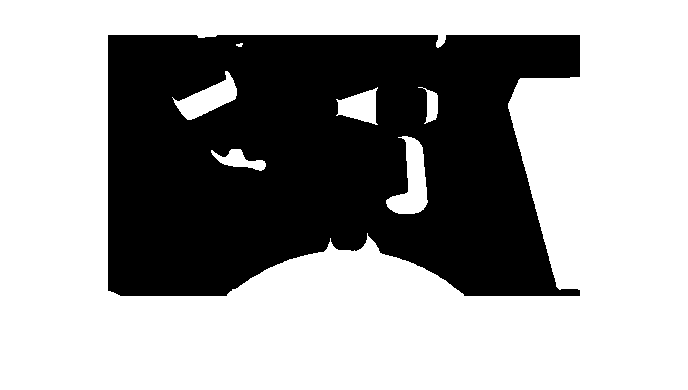

% Color feature extraction 
range = [0, 0.3]; 
channel = 2; 
HSV_img = rgb2hsv(source_img); 

img_saturation = inRange(HSV_img, channel, range); 
img_saturation = img_saturation(:,:, 1); 
imshow(img_saturation); 

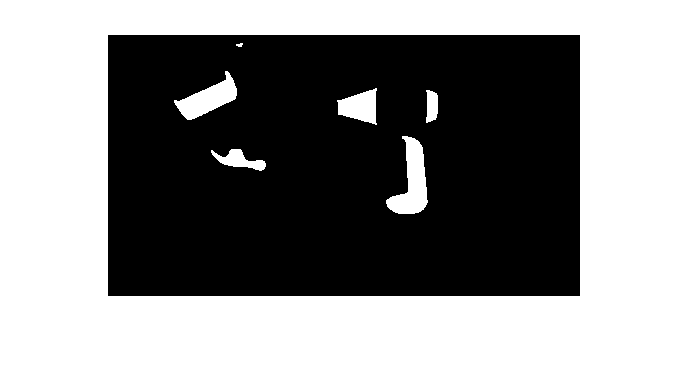


% clean borders 
img_cleaned = cleanImage(img_saturation, 'WFillAndClean'); 
imshow(img_cleaned); 

% Etiquetas -----------------------------------
green_label  = [120, 30]'; 
yellow_label   = [60, 5]'; 
blue_label = [235, 20]'; 

colors_labels = [green_label, blue_label, yellow_label] / 360; 

th_saturation = 0.5;  % Up
th_value = 0.5;  % Down

label_img_hsv = HSV_img ;  % copy HSV_img 
[R, C, channel] = size(HSV_img); 
is_in_range = @(value, center, radius) abs(center - value) < radius; 

imshow(hsv2rgb(HSV_img)); 

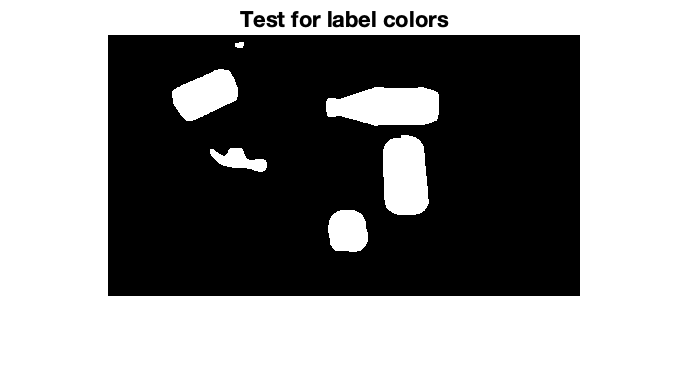

% HSV
for row = 1:R
    for col = 1:C
        px_val = label_img_hsv(row, col, :); 
        % Check for th in saturation and value 
        if px_val(2) >= th_saturation && px_val(3) <= th_value
            for color = 1:length(colors_labels)
                label = colors_labels(:, color)'; 
                Ce= label(1,1); Ra= label(1,2);
                
                if is_in_range(px_val(1), Ce, Ra)
                    label_img_hsv(row, col, color) = 255;
                else 
                    label_img_hsv(row, col, color) = 0;
                end
            end
        else 
            label_img_hsv(row, col, :) = [0, 0, 0];
        end
    end
end

% Total Image - Adding up each color
label_img_hsv_2 = label_img_hsv(:, :, 1) + label_img_hsv(:, :, 2) + label_img_hsv(:, :, 3); 
label_img_cleaned = cleanImage(label_img_hsv_2, 'WFillAndClean'); 

final_img =cleanImage(label_img_cleaned + img_cleaned, 'WFill'); 
imshow(final_img)
title("Test for label colors"); 